clear ; close all ; clc
w = logspace(-1,1.8,20)';
freq = w ./ (2*pi);
% sys = tf([1], [1./(2*pi) 1]);
fc = 1;
sys = tf([1 -2], [1/(2*pi*fc) 1 5]);
sys = minreal(sys)

sys =
 
     6.283 s - 12.57
  ---------------------
  s^2 + 6.283 s + 31.42
 
Continuous-time transfer function.




% sys = tf([1], [1 1]);
[R_test,I_test] = nyquist(sys, w);
R_test = squeeze(R_test);
I_test = squeeze(I_test);
C = R_test + I_test*1j;
n_rep = 3;
Fv = repmat(w, [n_rep 1]);
Cn = [];
for n = 1:n_rep
    noise = max(abs(real(C))) * interp1([0,1],[-1,1],rand(size(C))) ./ 10;
    Cn = [Cn , C + noise];
end

num = [1 1];
den = [1 1 1];
tau = false;
data_method = 'RI';
fit_method = 'lsqnonlin';
[model, h] = fit_complex(Cn, freq, num, den, tau, data_method, fit_method, true);


disp('Fit Model:')

Fit Model:


model.G

ans =
 
     6.409 s - 12.43
  ---------------------
  s^2 + 6.394 s + 32.17
 
Continuous-time transfer function.



model.fitpercent

ans = struct with fields:
    combined: 0.9830
        gain: 0.9715
       phase: 0.9945


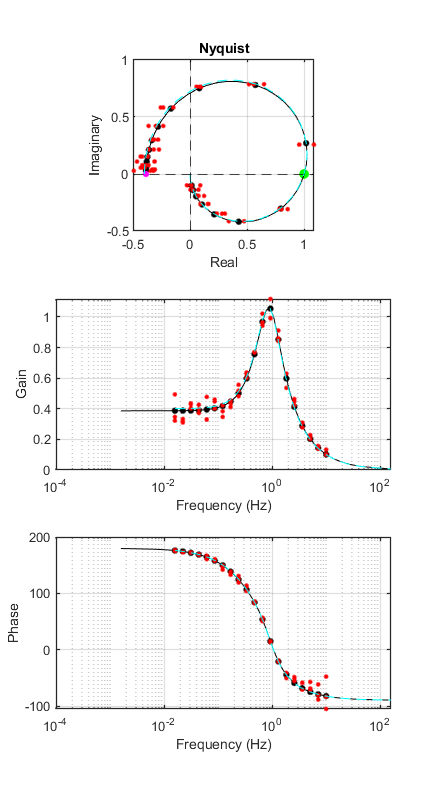


[mag,phase,wout] = bode(sys);
fout = wout ./ (2*pi);
[rr,ii] = nyquist(sys);

set(h.fig, 'CurrentAxes', h.ax(1))
plot(squeeze(rr), squeeze(ii), '--c')

set(h.fig, 'CurrentAxes', h.ax(2))
plot(fout, squeeze(mag), '--c')

set(h.fig, 'CurrentAxes', h.ax(3))
plot(fout, squeeze(phase), '--c')